## State space representation

clear all
%addpath("C:\Users\nicol\OneDrive\Documents\34746 - Robust & Fault Tolerent Control\Exercises\SA Tool\SaTool_3_0100\sa_tool_3_0100");
load('ECP_values.mat');
load('ECP502Data.mat');
% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s

s = tf('s');
%syms s
A = [0 1 0 0 0 0
    -k_1/J_1 -b_1/J_1 k_1/J_1 0 0 0
    0 0 0 1 0 0
    k_1/J_2 0 -(k_1+k_2)/J_2 -b_2/J_2 k_2/J_2 0
    0 0 0 0 0 1
    0 0 k_2/J_3 0 -k_2/J_3 -b_3/J_3];
B = [0 0
    1/J_1 0
    0 0
    0 1/J_2
    0 0
    0 0];
B = B(:,1); 

C = [  1 0 0 0 0 0
       0 0 1 0 0 0
       0 0 0 0 1 0 ];
C = C(3,:)

C =      0     0     0     0     1     0



D = [0 0
     0 0
     0 0];
D=0

D = 0


G0_tf = C*inv((s*eye(size(A,1),size(A,1))-A))*B;
[a,b] = ss2tf(A,B,C,D);
sys = ss2tf(A,B,C,D);

state = ss(A,B,C,D);
G0_2 = tf(state);

%bode(G0_2)


Q_c = diag([2 0 2 0 2.5 0.0024]);
R_c = diag([10]);
K_c = lqr(A, B, Q_c, R_c);

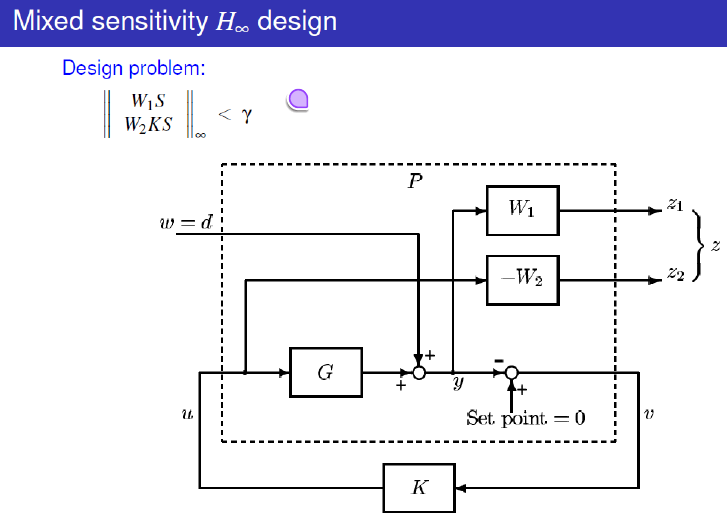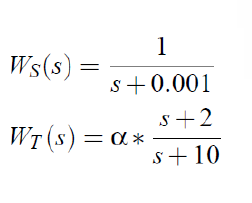

Ws = W1 

WT = W2

M = 2;     
A = 0.001;
omega_star = 1;  % Bandwidth
W1 = (s/M + omega_star) / (s + omega_star*A);
W2 = W1;    % Same weight on KS for now
W3 = 0;


[K_Hinf, Cl, Gam, Info] = mixsyn(G0_tf, W1, W2, W3, 'METHOD', 'lmi', 'GMIN', 0.9, 'GMAX', 1.1);

K_Hinf


K_Hinf =
 
  A = 
             x1        x2        x3        x4        x5        x6        x7        x8
   x1  -0.02611   -0.7164    0.5572    0.9964     1.759   -0.5643    -2.381   -0.9526
   x2      1.86    -4.141    -69.47    -63.38     32.71       162     333.9     134.5
   x3   -0.5638     63.75  0.004362   0.04984    -7.534     -5.86    -13.04    -5.249
   x4   0.09352    -5.994    -0.316    -2.632    -62.06    -29.44     -23.3    -9.561
   x5  -0.07777  -0.02051     3.164      20.9     -11.2     -79.5    -168.8    -67.99
   x6    0.1613   0.03831   0.04257    0.8139     1.967    -19.11    -44.41    -17.88
   x7    -2.706  -0.07007    0.0538   -0.1745    -1.201     7.302    -36.95    -14.52
   x8    -1.314  -0.02968    0.0198  -0.08501   -0.5191     3.085    -15.37    -6.042
 
  B = 
             u1
   x1    0.9944
   x2  0.006654
   x3   0.01499
   x4   0.03708
   x5  -0.02623
   x6   0.07856
   x7    -1.361
   x8   -0.6607
 
  C = 
             x1        x2        x3        x4

Gam

Gam = 0.6356

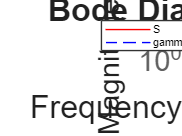

S_tf = 1/(1+G0_2*tf(K_Hinf));


figure;
bodemag(S_tf,'r',Gam/(W1),'b--');
legend('S', 'gamma/W2',Location='best');

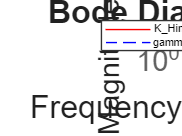

%saveas(gcf, 'figures/p2.png');
figure;
bodemag(K_Hinf*S_tf,'r',Gam/W2,'b--');
legend('K_Hinf*S', 'gamma/W2',Location='best');

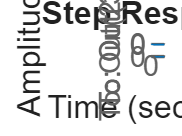

%saveas(gcf, 'figures/p2.png');

% Analyze
step(Cl)

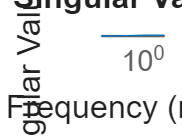

sigma(Cl)

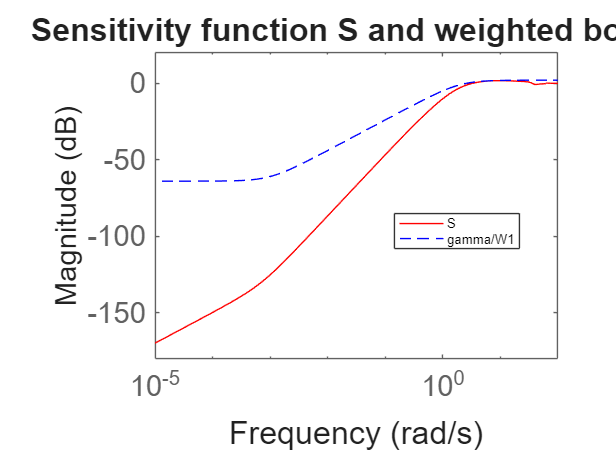

% Validation 

% s = tf('s');

% Bode plot of Sensitivity
figure;
bodemag(S_tf, 'r', Gam*(1/W1), 'b--');
legend('S', 'gamma/W1', 'Location', 'best');
title('Sensitivity function S and weighted bound');

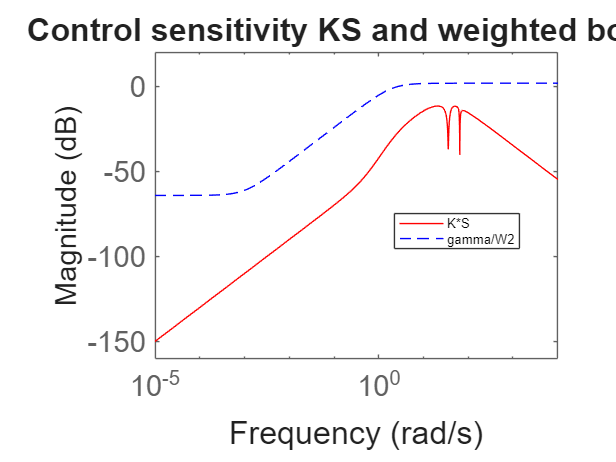


% Bode plot of KS (Control Sensitivity)
figure;
bodemag(K_Hinf*S_tf, 'r', Gam*(1/W2), 'b--');
legend('K*S', 'gamma/W2', 'Location', 'best');
title('Control sensitivity KS and weighted bound');

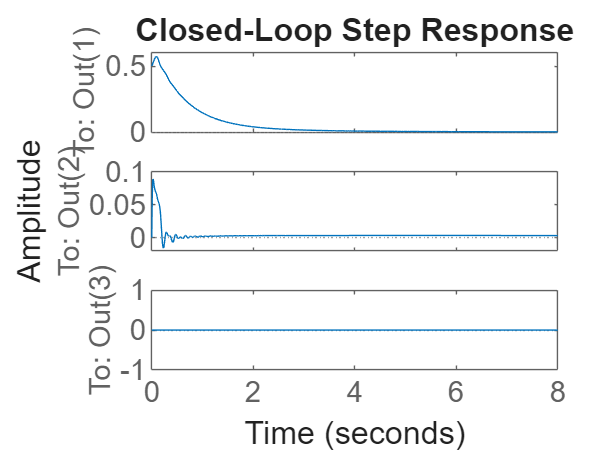



figure;
step(Cl)
title('Closed-Loop Step Response');

Question 10

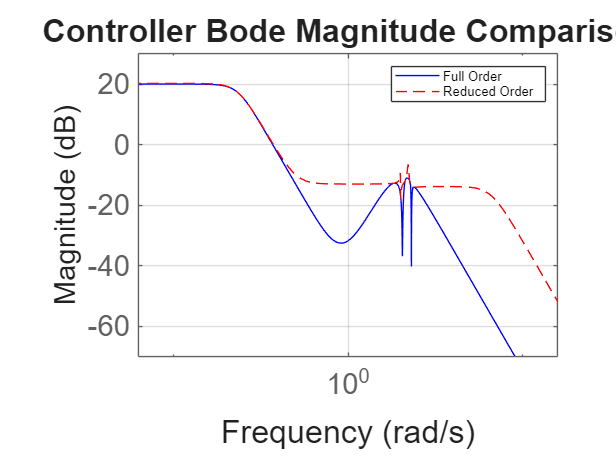


% Reduce the controller order
order_desired = 6;  % Try 6th order
K_reduced = balred(K_Hinf, order_desired);

K_reduced = hankelmr(K_Hinf, order_desired);


Cl_reduced = feedback(G0_tf * K_reduced, 1);

% Check poles
poles_Cl_reduced = pole(Cl_reduced);


% Poles and zeros of full controller
poles_full = pole(K_Hinf);
zeros_full = zero(K_Hinf);

% Poles and zeros of reduced controller
poles_reduced = pole(K_reduced);
zeros_reduced = zero(K_reduced);


figure;
bodemag(K_Hinf, 'b', K_reduced, 'r--');
legend('Full Order', 'Reduced Order');
title('Controller Bode Magnitude Comparison');
grid on;

Question 11

s = tf('s');
M = 2;             % Bandwidth shaping (high gain at low freq)
A = 0.001;         % To set low gain at high freq
omega_star = 1;    % Desired crossover (~1 rad/s ~ 1 sec response)

W1 = (s/M + omega_star) / (s + A*omega_star);
W2 = W1;  % Same weighting on K*S


% Large gamma bounds, no minimization – "h2-like" behavior
[K_H2, CL_H2, gamma_H2, info_H2] = mixsyn(G0_tf, W1, W2, 1e6);

step(CL_H2);

% Compare controllers 
figure;
bodemag(K_Hinf, 'b', K_H2, 'r--');
legend('H∞ Controller', 'H₂ Controller');
title('Controller Comparison');
grid on;


%Compare closed loop transfer functions
CL_Hinf = feedback(G0_tf * K_Hinf, 1);
CL_H2 = feedback(G0_tf * K_H2, 1);

figure;
bodemag(CL_Hinf, 'b', CL_H2, 'r--');
legend('H∞ Closed-Loop', 'H₂ Closed-Loop');
title('Closed-Loop Transfer Function Comparison');
grid on;




Question 12

% Export controller
K = ss(K_Hinf_red);  % or K_Hinf if not reduced




Question 13


% T: Complementary sensitivity function using reduced-order H∞ controller
T_red = feedback(G0_tf * K_Hinf_red, 1);

% Compute maximum gain of T (peak of magnitude)
[mag_T, freq_T] = norm(T_red, inf);

% Max multiplicative uncertainty that can be tolerated
max_uncertainty = 1 / mag_T;

fprintf('Max allowable multiplicative uncertainty at the output: %.4f\n', max_uncertainty);

% Plot T and compare with 1/W_Delta
figure;
bodemag(T_red, 'b', 'LineWidth', 1.5);
hold on;
bodemag(1/mag_T, 'r--', 'LineWidth', 1.5);
legend('|T|', '1 / ||T||_∞ bound');
title('Complementary Sensitivity and Robust Stability Bound');
grid on;





Question 14


% Reuse original A, B, C, D
A_nom = A;
A_new = A;
J1_nom = 0.0025;
J1_new = 0.0325;

% Replace the relevant A matrix entries for J1 in perturbed model
A_new(2,:) = [-k_1/J1_new -b_1/J1_new k_1/J1_new 0 0 0];
B_new = [0; 1/J1_new; 0; 0; 0; 0];

% Create systems
G0 = ss(A_nom, B, C, D);
G_new = ss(A_new, B_new, C, D);

% Compute transfer functions
G0_tf = tf(G0);
Gnew_tf = tf(G_new);

% Frequency range
omega = logspace(-1, 2, 500);
[mag_G0, ~] = bode(G0_tf, omega);
[mag_Gnew, ~] = bode(Gnew_tf, omega);

% Compute multiplicative uncertainty (element-wise)
mag_G0 = squeeze(mag_G0);
mag_Gnew = squeeze(mag_Gnew);
WI = abs((mag_Gnew - mag_G0) ./ mag_G0);

% Plot result
figure;
semilogx(omega, WI, 'b', 'LineWidth', 1.5);
xlabel('Frequency [rad/s]');
ylabel('|Δ(jω)|');
title('Lower bound for uncertainty weight W_I');
grid on;

% Compare to previous max allowed uncertainty
yline(max_uncertainty, 'r--', 'LineWidth', 1.5);
legend('|Δ(jω)| from J1 change', 'Max allowed from Q13');



Question 15

s = tf('s');

% Weight W1 (Sensitivity) - tracking requirement
M = 2; A = 0.001; omega_star = 1;
W1 = (s/M + omega_star)/(s + omega_star*A);

% Weight W2 (Control sensitivity) - limits control action
% High-pass filter, scaled to reduce bandwidth
W2 = (s + 0.5)/(0.05*s + 0.001);  % Tuned to limit fast response

% Weight W3 (Complementary sensitivity) - model uncertainty
W3 = (0.833*s)/(s + 0.089);

% Scale W1 and W2 to push gamma below 1
W1 = W1 / 1.1;
W2 = W2 / 1.1;

% Plant (SISO top disk angle)
G = ss(A,B,C,D);  % Already only top disk used

% H-infinity controller design
[K_Hinf_robust, CL_robust, gamma_robust, info_robust] = mixsyn(G, W1, W2, W3, ...
    'GMIN', 0.9, 'GMAX', 1.5, 'METHOD', 'lmi');

% Bode plots of closed-loop sensitivity functions
L = G*K_Hinf_robust;
S = feedback(1, L);
T = feedback(L, 1);
KS = K_Hinf_robust*S;

figure;
bodemag(S, 'r', 1/W1, 'b--'); grid on;
legend('Sensitivity S', '1/W1'); title('Sensitivity Function');

figure;
bodemag(KS, 'r', 1/W2, 'b--'); grid on;
legend('Control Sensitivity KS', '1/W2'); title('Control Sensitivity Function');

figure;
bodemag(T, 'r', 1/W3, 'b--'); grid on;
legend('Complementary Sensitivity T', '1/W3'); title('Model Uncertainty Handling');

% Step response analysis
figure;
step(feedback(G*K_Hinf_robust,1)); grid on;
title('Closed-loop Step Response');

% Display gamma value
disp(['Achieved gamma: ', num2str(gamma_robust)]);



Question 16



% Use this in MATLAB to launch and simulate
open_system('your_simulink_model');
 
% Set J1 in the base workspace for the model to use
J1 = 0.0025;
sim('your_simulink_model');

J1 = 0.0325;
sim('your_simulink_model');



% Plot both responses for comparison:
figure;
plot(t_nominal, y_nominal, 'b', 'LineWidth', 1.5); hold on;
plot(t_heavy, y_heavy, 'r--', 'LineWidth', 1.5);
legend('Nominal J1', 'Increased J1');
xlabel('Time (s)'); ylabel('Top Disk Angle (rad)');
title('Step Response Comparison');
grid on;







